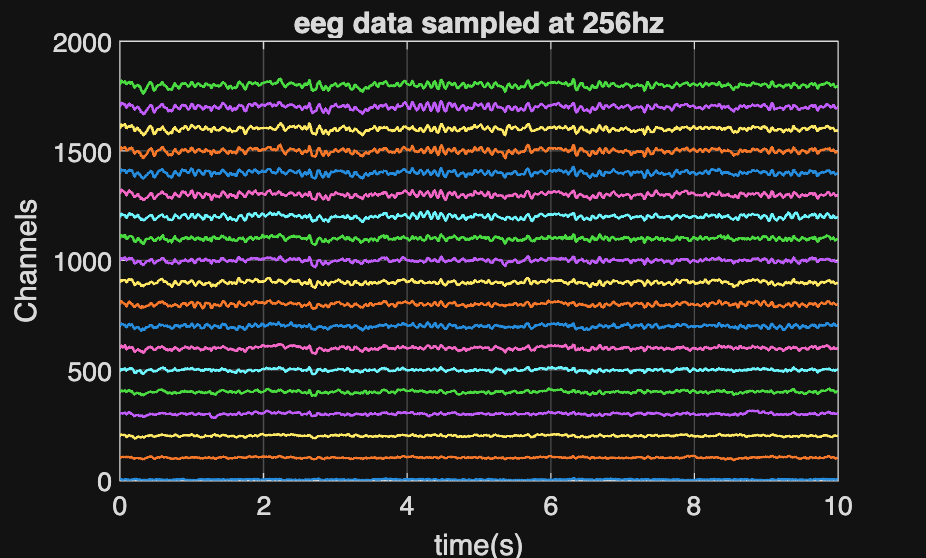

%{
TASK 0:
An EEG file(.mat format) has 19 channel EEG recordings 
of a participant which is of duration 10 seconds at a sampling frequency 256 Hz(Dimension: 19 X 2560). 
The data is already preprocessed (i.e.) band-pass filtered, eye and muscle artefacts removed.

Plot the EEG signals before and after downsampling.
%}

%{
19 channels= 19 electrodes. 256hz sampling rate for 10seconds will result
to 2560 samples in total.
so we can construct a matrix of 19x2560, each row corresponds to an
electrode(channel) and each column corresponds to a sample.
    s1 s2 s3 ... s2560
ch1
ch2
ch3
...
ch19
%}

%{
what is downsamlping?
used to decrease the sampling rate of a signal by an integer factor(M).
why?
Reduced storage and computation:lowers the storage and processing requirements
Bandwidth reduction:useful for processing specific parts of a signal

for the given matrix, we can downsample by decreasing sampling rate to
fs/2, ie, 128hz. M=2.
so 19x128x10. total time duration remains same .only sampling rate has
decreased in downsampling.
%}

eeg = S06V01;%extract the 19×2560 matrix
fs = 256;
T = 10;
N = fs*T;
t = (0:N-1)/fs;%sampled timestamps, created 2560 timestamps

%plot data sampled at 256hz,channels are offseted vertically so they dont overlap
offset = 100;%vertical spacing between channels
shifted = eeg + (0:18)' * offset;%add offset to each channel
% (0:18)'--> creates a column vector, of values,1,2,3...18, multiplied
% offset, and is added to each channel(lifts each channel equally spaced)
figure;
%plot(x, Y) function expects each column of Y to be a separate plotted signal.
plot(t, shifted', 'LineWidth', 1);%shifted' is transposed(2560x19),t (1,2560)
title("eeg data sampled at 256hz");
xlabel("time(s)"); ylabel("Channels");
xlim([0 T]); grid on;

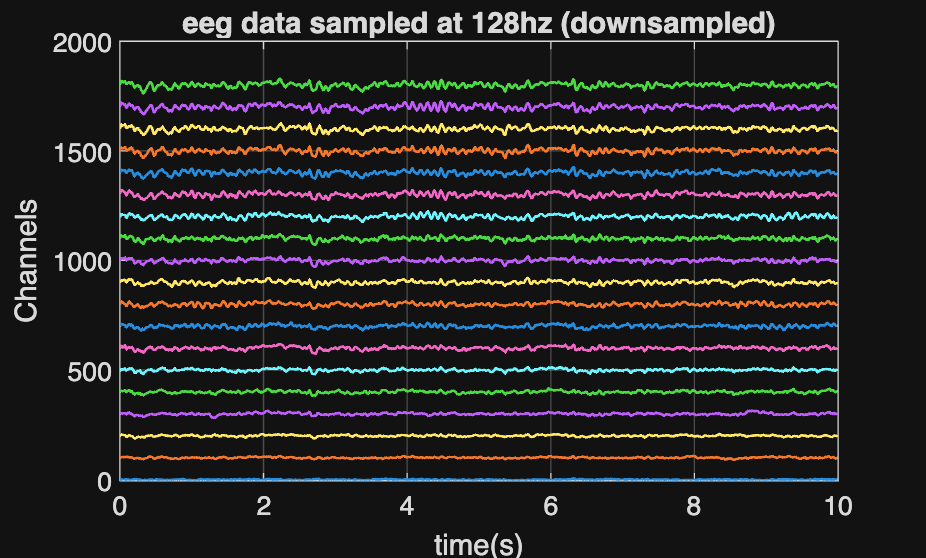


M=2;%downsamping factor
fs=fs/M;
N=N/M;
t = (0:N-1)/fs;
eeg_ds = eeg(:, 1:M:end);% take every Mth sample

%plot data sampled at 128hz (downsampledsame offset style)
shifted_ds = eeg_ds + (0:18)' * offset;% reuse same offset value
figure;
plot(t, shifted_ds', 'LineWidth', 1);
title("eeg data sampled at 128hz (downsampled)");
xlabel("time(s)"); ylabel("Channels");
xlim([0 T]); grid on;

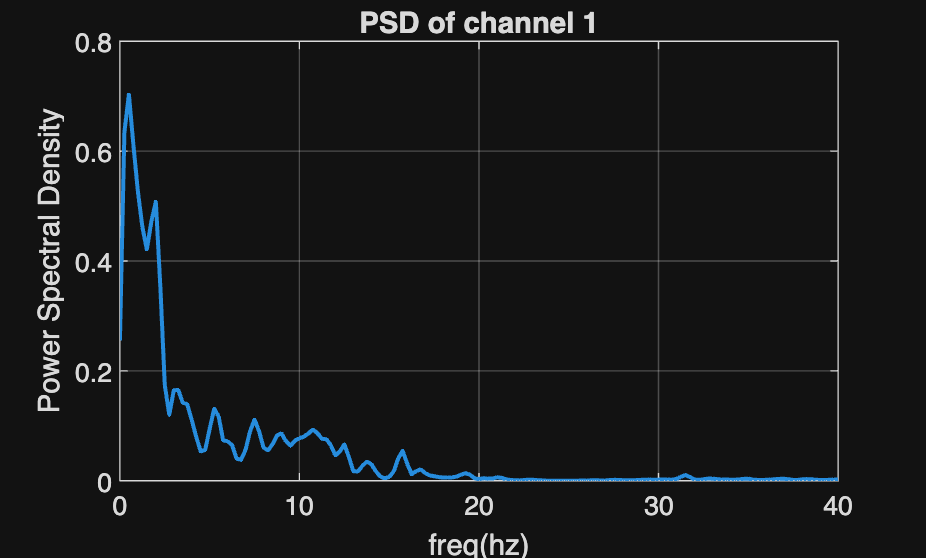

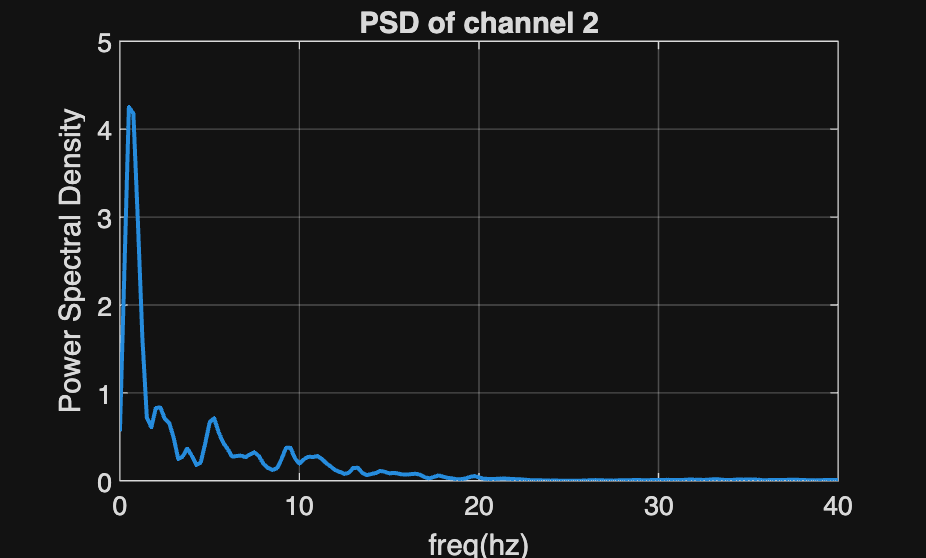

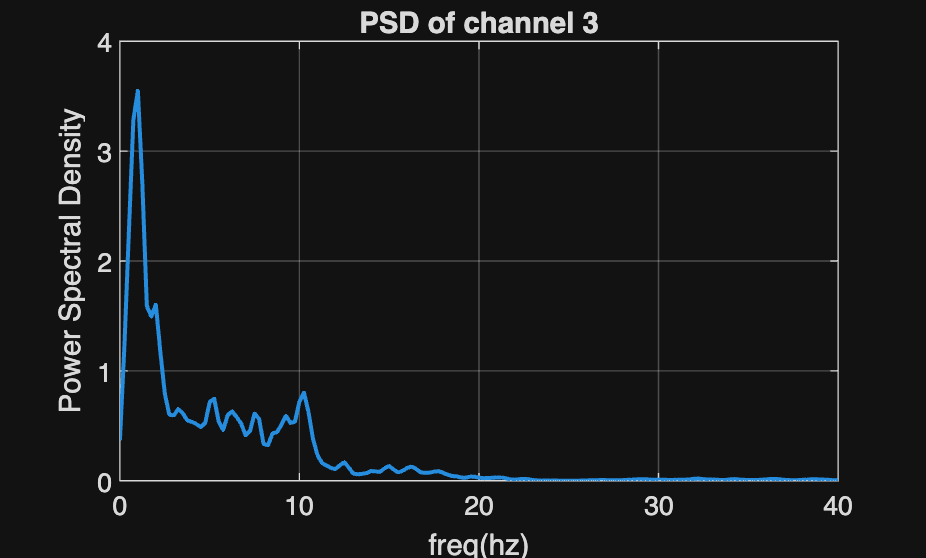

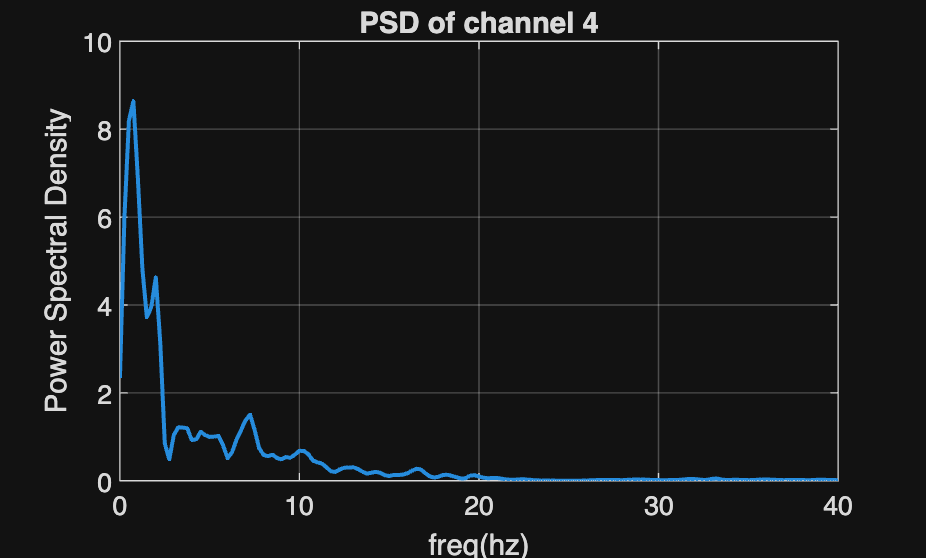

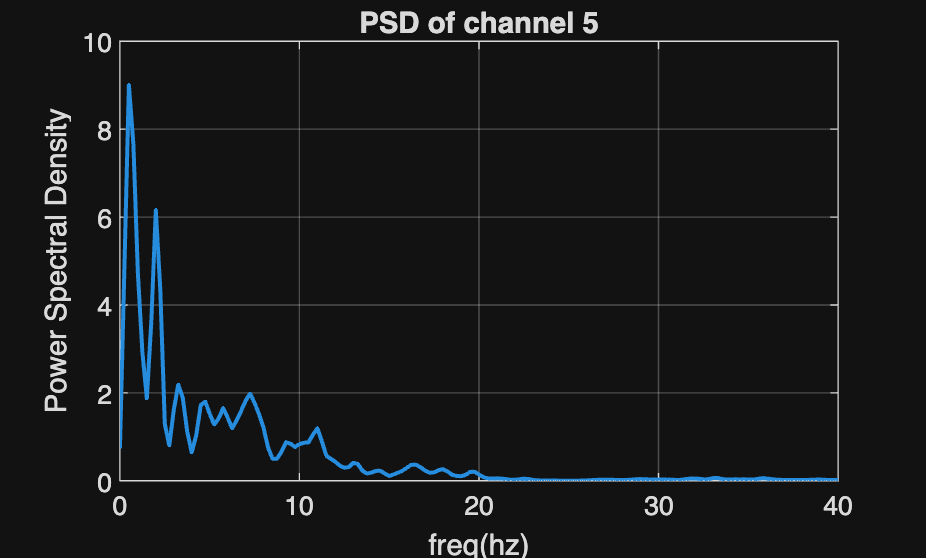

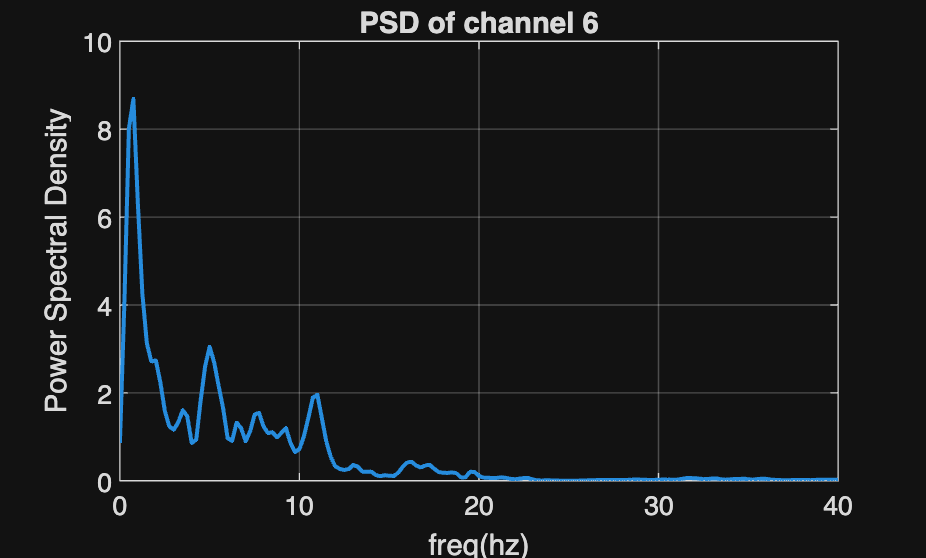

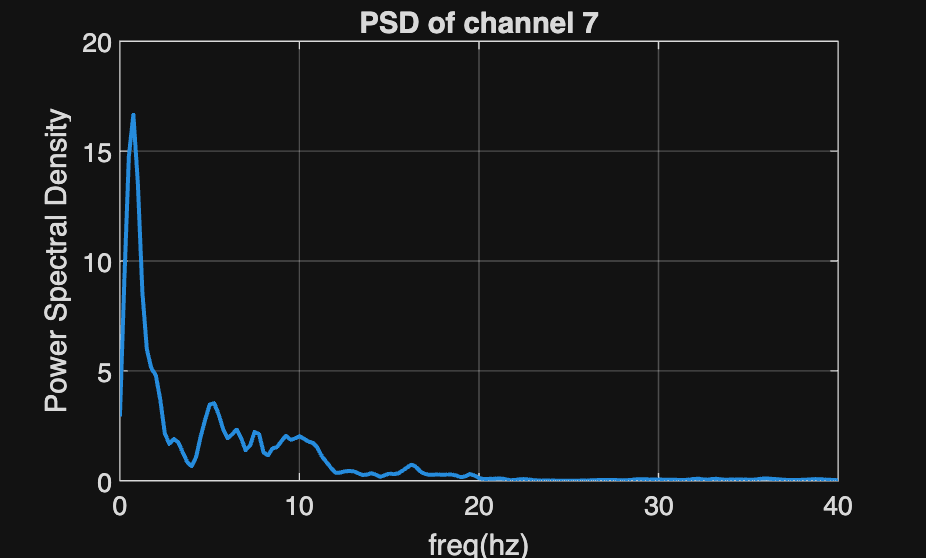

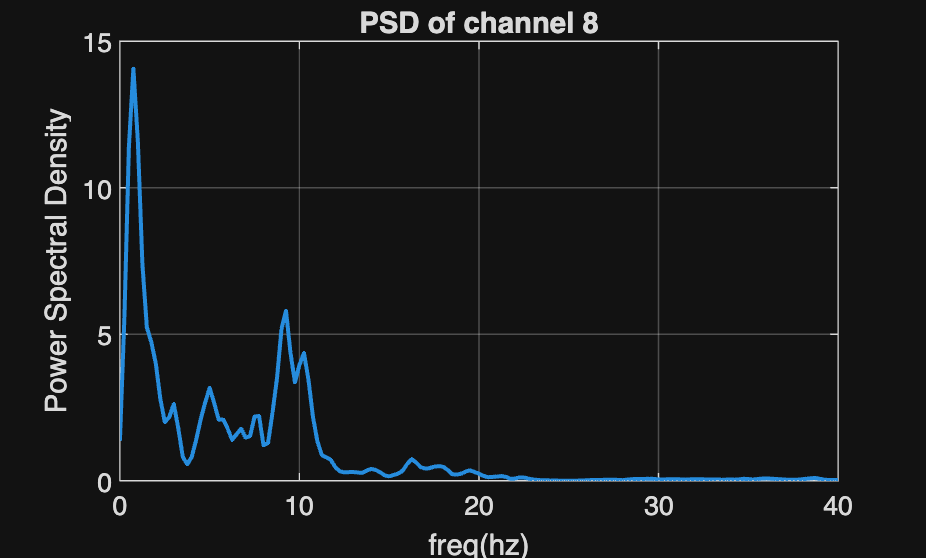


%{
TASK 1: 
    Power Spectral Density (PSD) Analysis  
    Compute the Power Spectral Density (PSD) for each
    EEG channel in the provided preprocessed signal.     
    Use appropriate techniques 
    (e.g., Welch's method) to calculate the PSD and
    plot corresponding figures for each channel as subplots.  
%}
fs = 256;%back to 256hz sampling rate

%plotting 19 seperate channel PSD plots
for ch = 1:19 %loop iterates over 19 channels, matlabs aray indexing start at 1
    x = eeg(ch, :); %(1,2560), extraxts one channel signal
    [Pxx, f] = pwelch(x, [], [], [], fs);%computes psd using welch's method
    figure;
    plot(f, Pxx, 'LineWidth', 1.5);
    xlim([0 40]);%look only at eeg bandsw
    grid on;
    title(sprintf("PSD of channel %d", ch));
    xlabel("freq(hz)");
    ylabel("Power Spectral Density");
end

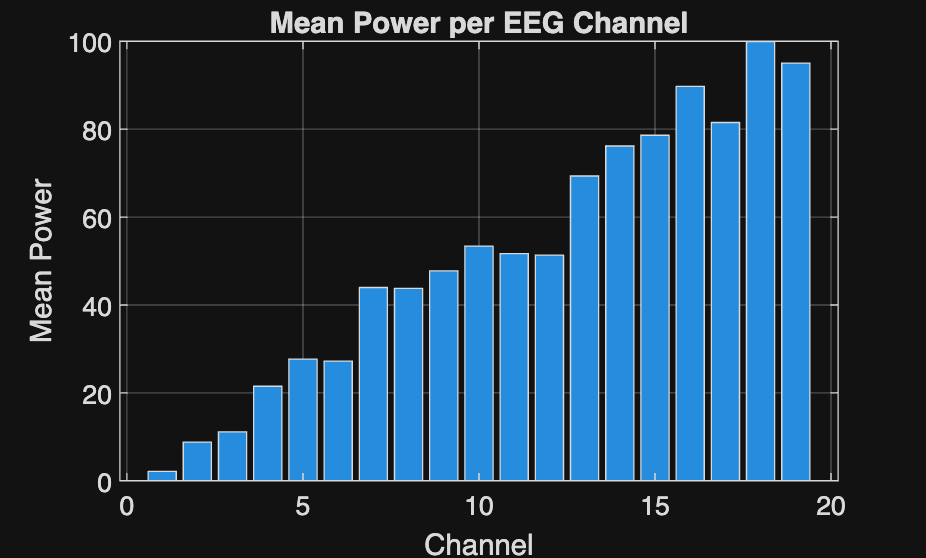


%{
TASK 2:
   Mean Power Calculation and Visualization  
   Calculate the mean power of each channel across the signal.  
   Plot the mean power values for all channels in a clear and 
   labeled graph (line/bar/ of your choice).  
%}

mean_power = mean(eeg.^2, 2);% mean of squared values, per row,channel
%eeg.^2 gives squares of each sample in a channel then, (,2) gives mean in
%the 2nd dimension, takes average over row

figure;
bar(mean_power);
xlabel("Channel");
ylabel("Mean Power");
title("Mean Power per EEG Channel");
grid on;

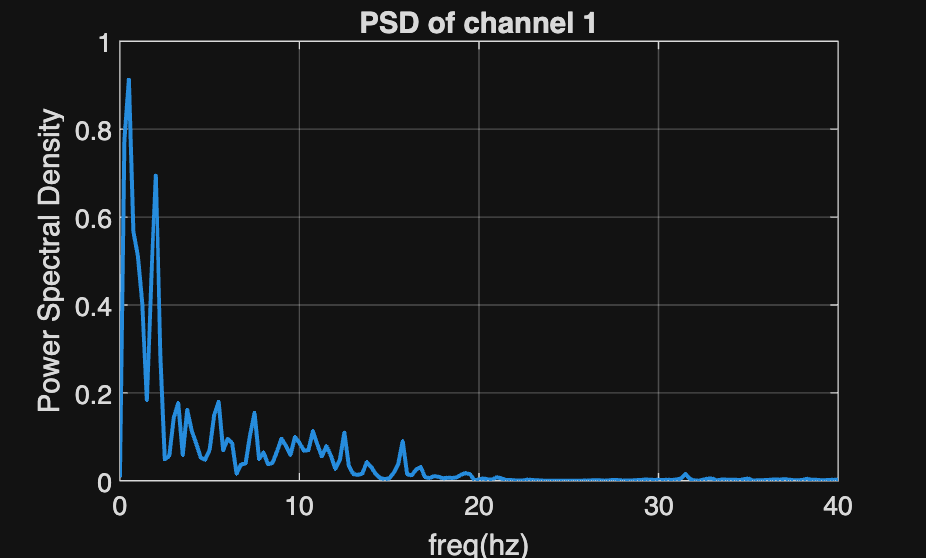

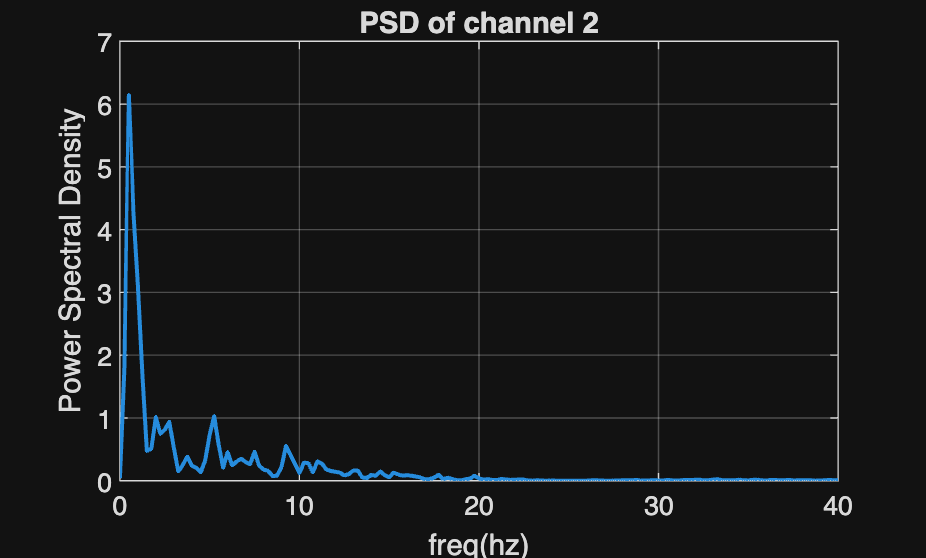

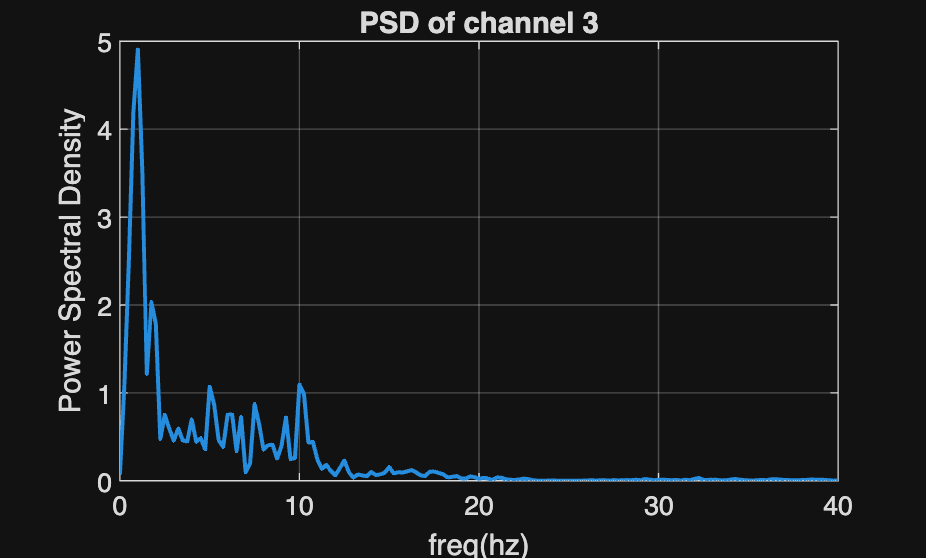

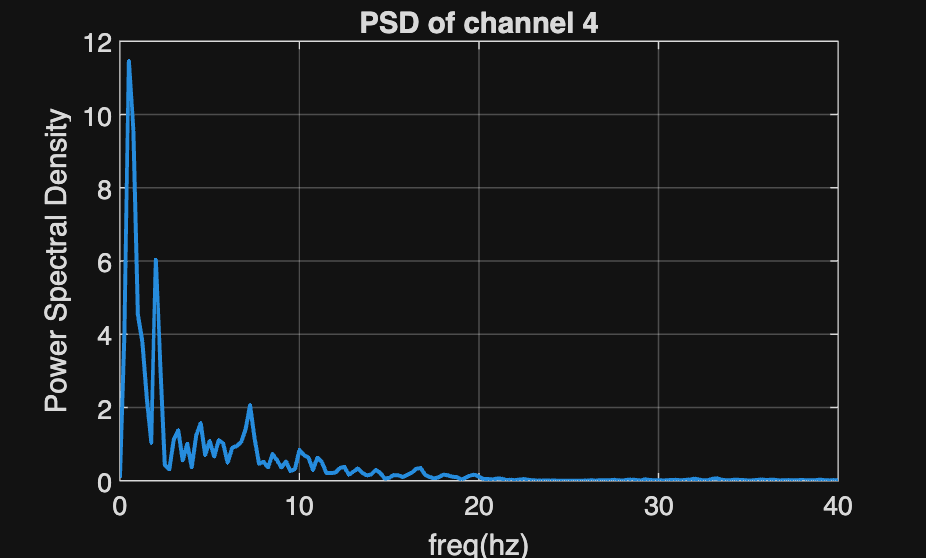

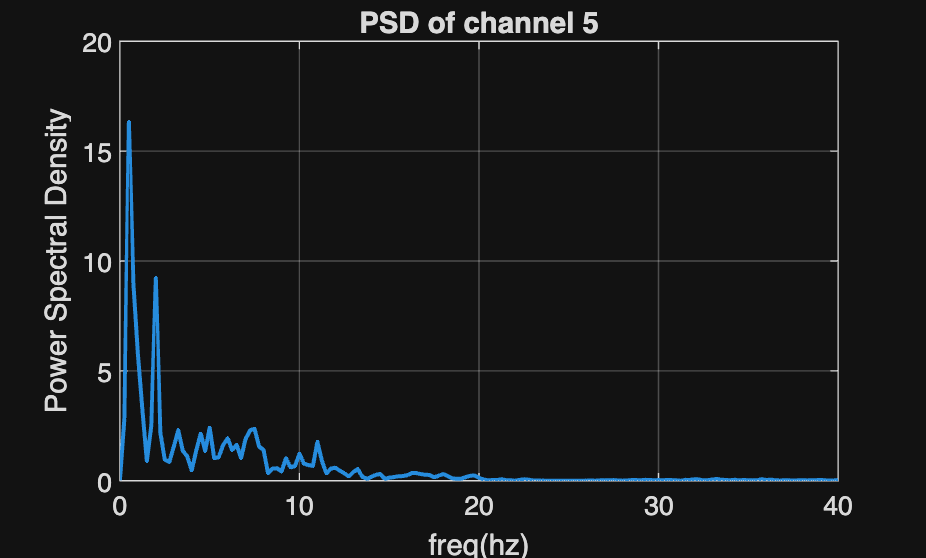

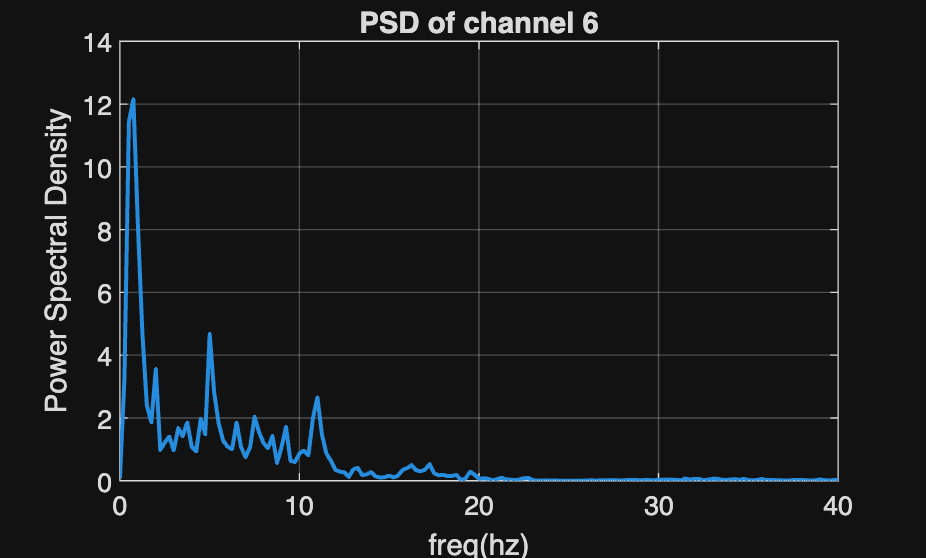

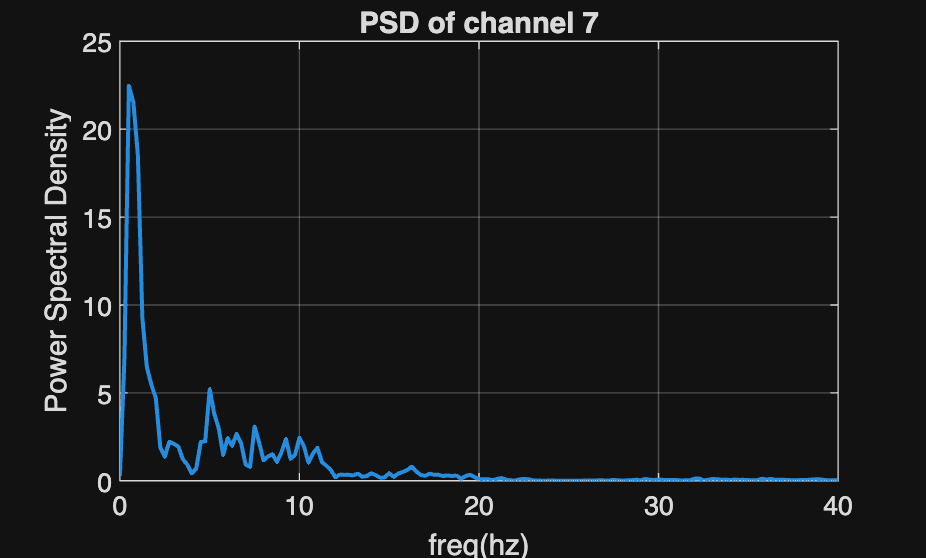

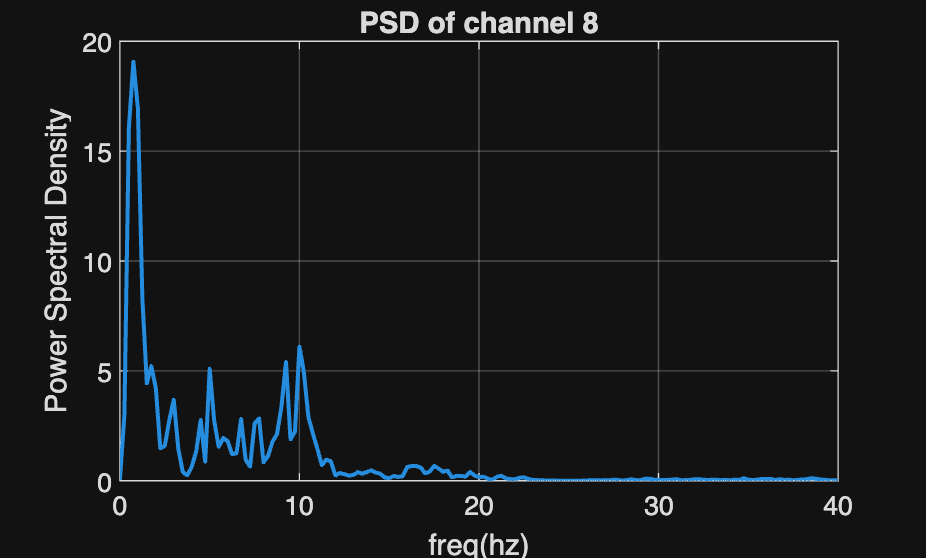



%{
TASK 3:
   Downsampling and Reanalysis  
   Downsample the EEG signal to 128 Hz while preserving signal integrity.  
   Repeat Tasks 1 and 2 on the downsampled signal.  
%}
%REPEATING TASKS 1 AND 2 FOR DOWNSAMPLED SIGNAL

M=2;%downsamping factor 
fs=fs/M;
N=N/M;
ts=1/fs;
t = (0:N-1)/fs;
eeg_ds = eeg(:, 1:M:end);% take every Mth sample

%plotting 19 seperate channel PSD plots
for ch = 1:19 
    x = eeg_ds(ch, :);
    [Pxx, f] = pwelch(x, 512, 256, 512, fs);
    figure;
    plot(f, Pxx, 'LineWidth', 1.5);
    xlim([0 40]);
    grid on;
    title(sprintf("PSD of channel %d", ch));
    xlabel("freq(hz)");
    ylabel("Power Spectral Density");
end

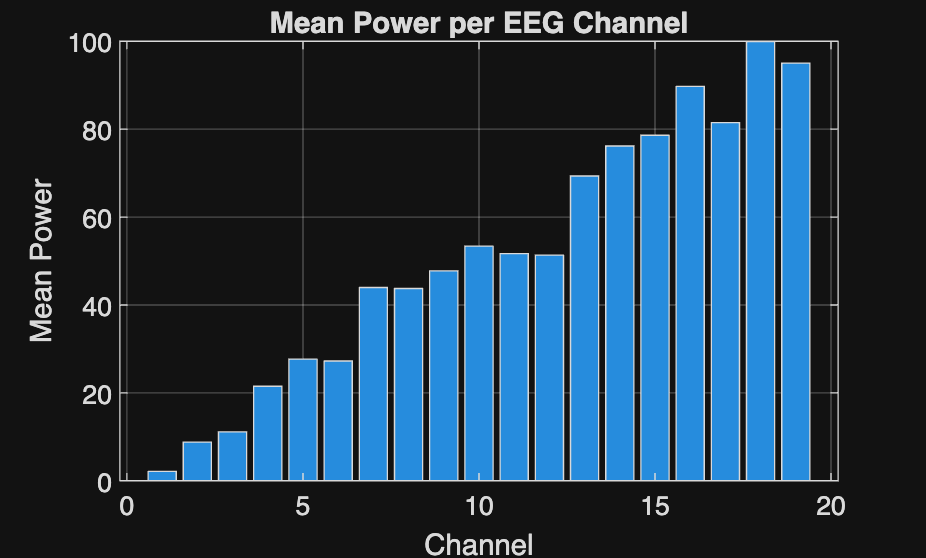


mean_power = mean(eeg_ds.^2, 2);

figure;
bar(mean_power);
xlabel("Channel");
ylabel("Mean Power");
title("Mean Power per EEG Channel");
grid on;